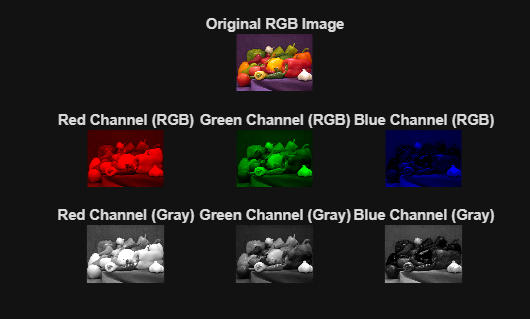

%Computer vision hands-on Tutorial Class - Program 1
% 1. Read an in-built RGB image
img = imread('peppers.png');   % you can replace with other images if needed

% 2. Convert the image to its equivalent matrix form
img_matrix = double(img);   % converting to numeric matrix (optional)

% 3. Split the image into its R, G, and B components
R = img(:,:,1);   % Red channel
G = img(:,:,2);   % Green channel
B = img(:,:,3);   % Blue channel

% 4. Create RGB images for each channel (keeping one channel, zeroing others)
red_img   = cat(3, R, zeros(size(G)), zeros(size(B)));
green_img = cat(3, zeros(size(R)), G, zeros(size(B)));
blue_img  = cat(3, zeros(size(R)), zeros(size(G)), B);

% ----- Display Section -----
figure;

% Original
subplot(3,3,2); imshow(img); title('Original RGB Image');

% RGB representations of channels
subplot(3,3,4); imshow(red_img); title('Red Channel (RGB)');
subplot(3,3,5); imshow(green_img); title('Green Channel (RGB)');
subplot(3,3,6); imshow(blue_img); title('Blue Channel (RGB)');

% Grayscale representations of channels
subplot(3,3,7); imshow(R); colormap(gca, gray); title('Red Channel (Gray)');
subplot(3,3,8); imshow(G); colormap(gca, gray); title('Green Channel (Gray)');
subplot(3,3,9); imshow(B); colormap(gca, gray); title('Blue Channel (Gray)');

% 5. Optionally save each channel image
imwrite(red_img, 'Red_Channel_RGB.png');
imwrite(green_img, 'Green_Channel_RGB.png');
imwrite(blue_img, 'Blue_Channel_RGB.png');
imwrite(R, 'Red_Channel_Gray.png');
imwrite(G, 'Green_Channel_Gray.png');
imwrite(B, 'Blue_Channel_Gray.png');

% Save the complete figure
saveas(gcf, 'RGB_Channel_Analysis.png');

disp('✓ Figure saved as RGB_Channel_Analysis.png');

✓ Figure saved as RGB_Channel_Analysis.png
